Both transmitters transmit at 10 GHz, and we model their signal bandwidth as 400 MHz. These are the operating parameters of the receive radio.

fc = 10e9;
fsBaseband = 400e6;

## Transmit Signals

The signal of interest is an FM audio signal. We are using this kind of signal to demonstrate the transmission of audio data, but any kind of waveform could be used.

We read the audio signal from a default matlab audio file and create the signal of interest using the FM Modulator.

[y, fsAudio] = audioread('guitartune.wav');
modulator   = comm.FMModulator(SampleRate=fsBaseband,FrequencyDeviation=fsBaseband/3);
soi = modulator(y(1000:end));

We create a complex noise signal to create interference across the entire bandwidth.

interference = randn(length(soi),1,like=1i);

We compare the transmit and receive spectrums in the frequency domain.

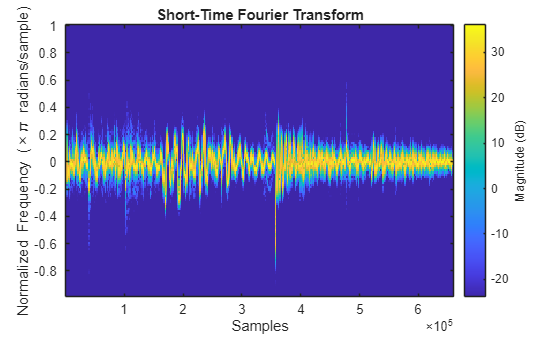

stft(soi);

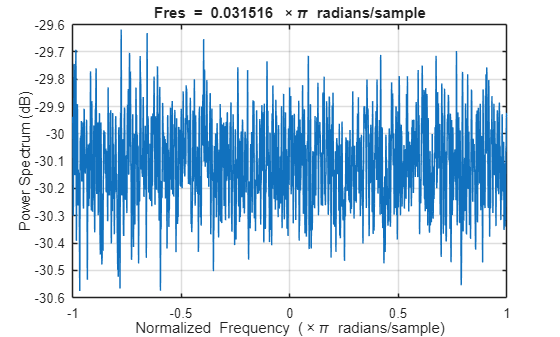

pspectrum(interference);

## Transmit Antennas

The transmitter transmitting the signal of interest and the transmitter transmitting the interference are both modelled as transmitting with an isotropic radiation pattern.

soiTransmitter = phased.IsotropicAntennaElement;
interferenceTransmitter = phased.IsotropicAntennaElement;

The antenna pattern of an isotropic element is uniform in all directions.

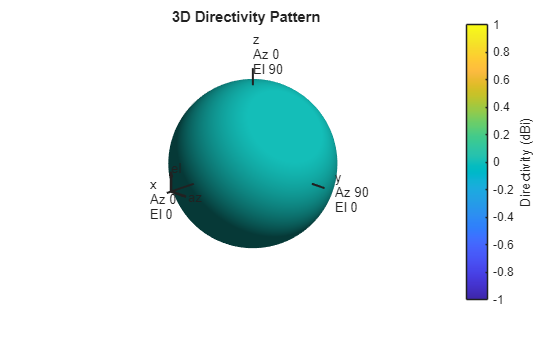

soiTransmitter.pattern(fc);

Use the phased.Radiator to radiate the transmitted signals.

soiRadiator = phased.Radiator(Sensor=soiTransmitter,OperatingFrequency=fc);
intRadiator = phased.Radiator(Sensor=interferenceTransmitter,OperatingFrequency=fc);

Set the initial position of the signal of interest and the interferer.

soipos = [5;2;-3];
intpos = [5;-2;2];

## Signal Propagation

Use a free space propagation model.

soiChannel = phased.FreeSpace(OperatingFrequency=fc,SampleRate=fsBaseband);
intChannel = phased.FreeSpace(OperatingFrequency=fc,SampleRate=fsBaseband);

## Receive Antenna Array

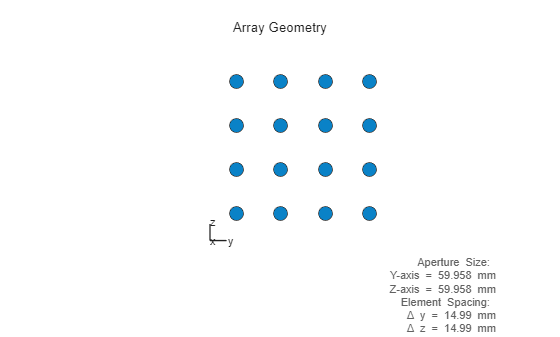

spacing = freq2wavelen(fc)/2;
rxArray = phased.URA(Size=[4 4],ElementSpacing=[spacing spacing]);
viewArray(rxArray);

Use the phased.Collector to receive the signal and interference.

rxCollector = phased.Collector(Sensor=rxArray,OperatingFrequency=fc);

The receiver is positioned at the origin.

rxpos = [0;0;0];

## Receive Radio

The radio is modeled with just gain and additive noise. All second order effects are ignored.

receiver = phased.Receiver(Gain=20,NoiseFigure=10,ReferenceTemperature=300,SampleRate=fsBaseband);

## Signal Processing

A MUSIC estimator is created to perform 2D direction of arrival estimation.

music = phased.MUSICEstimator2D(SensorArray=rxArray,OperatingFrequency=fc,AzimuthScanAngles=-90:90,...
    ElevationScanAngles=-90:90,NumSignalsSource="Property",NumSignals=2,DOAOutputPort=true);

An MVDR beamformer is created to beamform the incoming signal.

mvdr = phased.MVDRBeamformer(SensorArray=rxArray,OperatingFrequency=fc,TrainingInputPort=true,...
    DirectionSource="Input port",WeightsOutputPort=true);

## Data Simulation

Create the simulation control.

control = SimulationControl(rxpos,soipos,intpos);

Set the estimator to look for two signals - the signal of interest and the interference.

release(music);
music.NumSignals = 2;

Specify the number of samples to propagate in the loop.

nsamples = 100;
startidx = 1;
endidx = startidx+nsamples-1;

Run the data simulation loop collecting signal of interest and interference.

while ~control.shouldStop()

Get the updated positions.

rxpos = control.getRxPos();
soipos = control.getSoiPos();
intpos = control.getIntPos();

Get the next set of samples.

if endidx > length(soi)
    startidx = 1;
    endidx = startidx + nsamples;
end

Get the signal of interest and interference to propagate.

csoi = soi(startidx:endidx);
cint = interference(startidx:endidx);
startidx = endidx;
endidx = startidx + nsamples - 1;

Collect training data if necessary

if control.shouldCollectTrainingData()
    [trainSig,intdoa] = helperCollectTrainingData(rxpos,intpos,cint,intRadiator,intChannel,rxCollector,receiver,music);
    control.trainingDataCollected();
end

Get the angle of the interferer and signal of interest.

[soirange,soiang] = rangeangle(soipos,rxpos);
[intrange,intang] = rangeangle(intpos,rxpos);

Transmit the waveforms towards the receiver.

txSoi = soiRadiator(csoi,-soiang);
txInt = intRadiator(cint,-intang);

Pass the signals through the propagation channels.

propSoi = soiChannel(txSoi,soipos,rxpos,[0;0;0],[0;0;0]);
propInt = intChannel(txInt,intpos,rxpos,[0;0;0],[0;0;0]);

Receive the interference signal at the receive array.

collectSig = rxCollector([propInt propSoi],[intang soiang]);

Pass the signal through the receiver.

rxSig = receiver(collectSig);

Apply MUSIC algorithm.

[musicSpec,doa] = music(rxSig);
control.plotMUSICSpectrum(music,musicSpec,soiang,intang);

Calculate the signal of interest DOA using the known interference DOA.

[~,intIdx] = min(sum((doa-intdoa).^2,1));
soiIdx = [true true];
soiIdx(intIdx) = false;
soiDoa = doa(:,soiIdx);

Generate the MVDR weights pointing the beamformer towards the signal of interest.

[mvdrsig,wmvdr] = mvdr(rxSig,trainSig,soiDoa);
control.plotBeamPattern(fc,rxArray,wmvdr,soiang,intang);

Calculate the SINR by subtracting the signal of interest from the noisy signal after shifting and scaling.

soiDelay = soirange/physconst('LightSpeed')*fsBaseband;
snr = helperCalculateSNR(mvdrsig,csoi,soiDelay);

Plot the new snr point.

control.plotSnr(snr);

Enforce plotting.

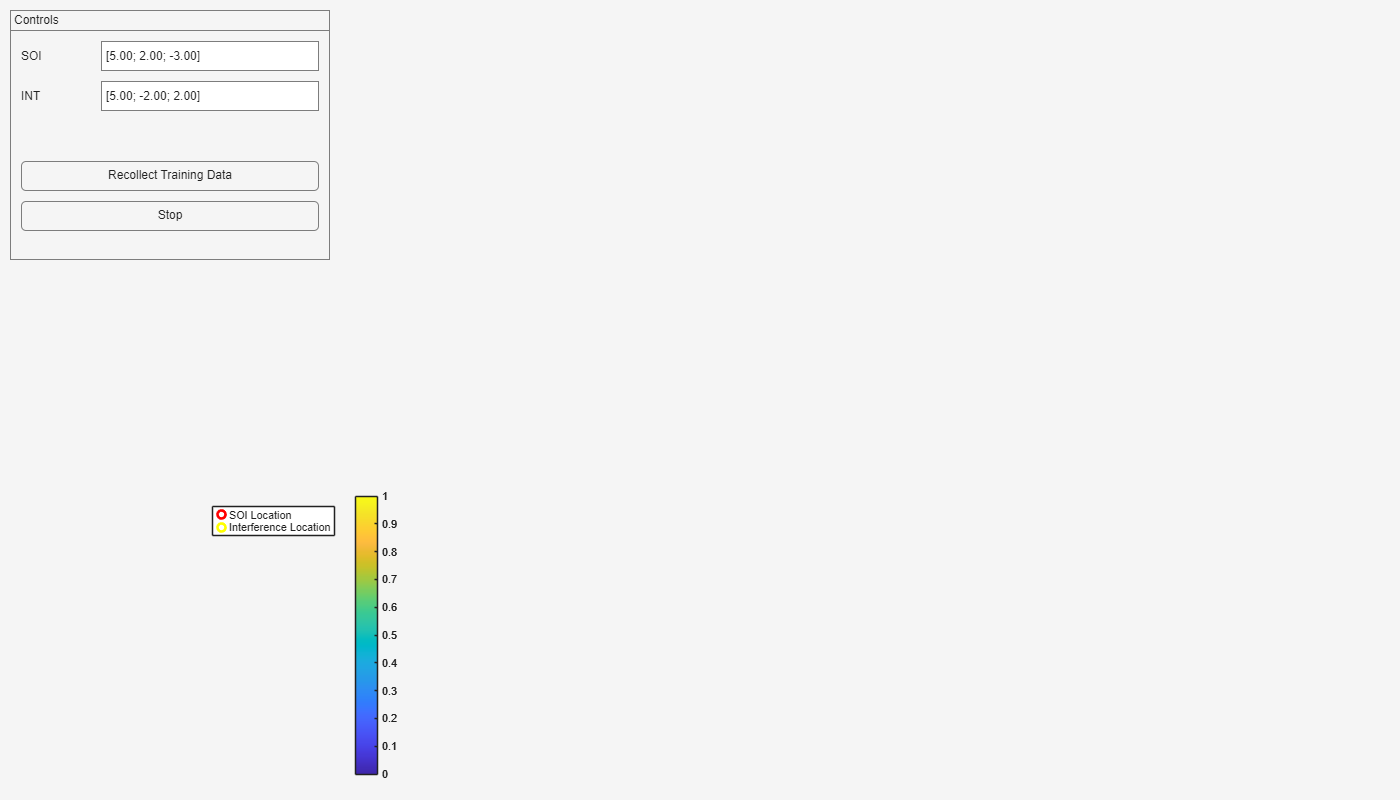

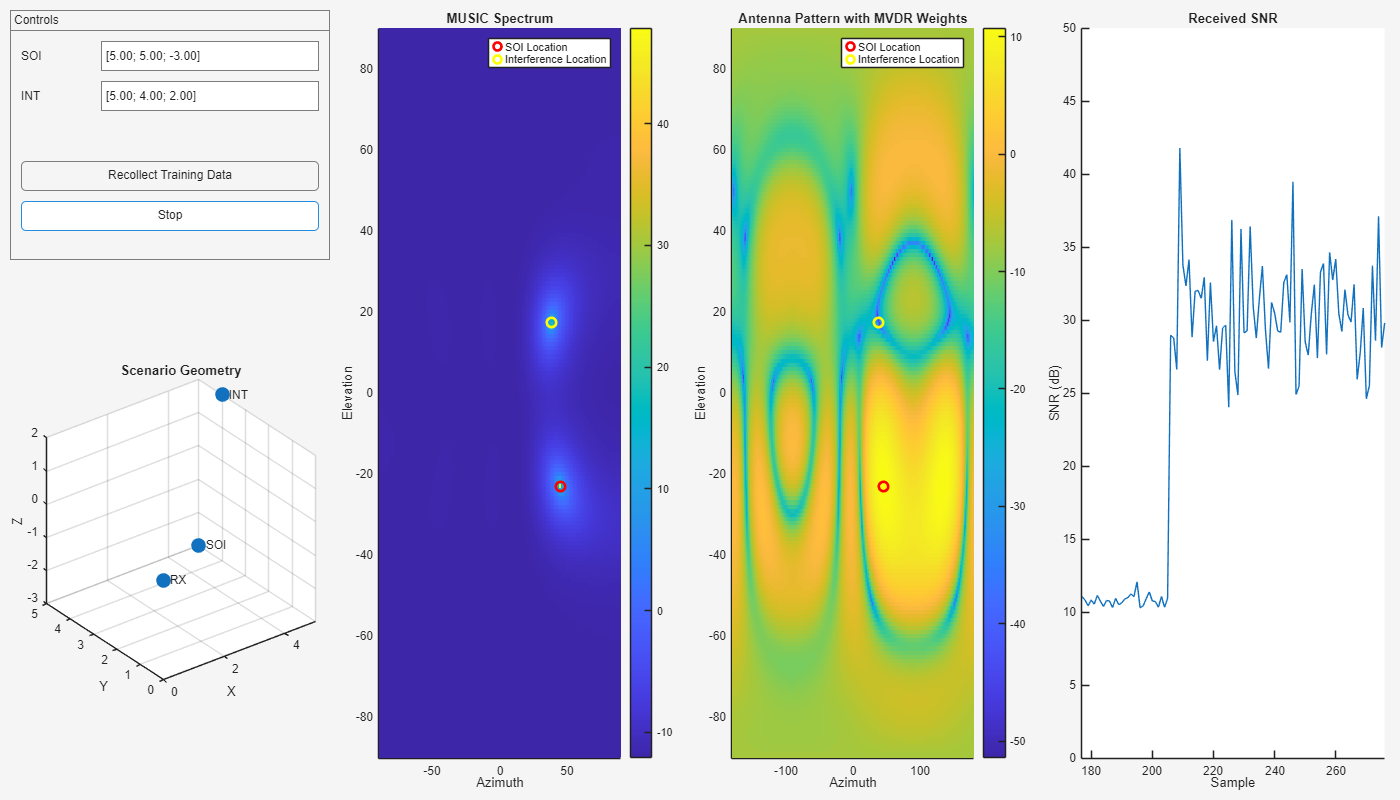

drawnow;
end

## Helper Functions

function [trainSig,intdoa] = helperCollectTrainingData(rxpos,intpos,interference,intRadiator,intChannel,rxCollector,receiver,music)
% Collect training data with only the jamming signal present.

% Set MUSIC to estimate single signal
ogns = music.NumSignals;
release(music);
music.NumSignals = 1;

% Get interference AoA
[~,intang] = rangeangle(intpos,rxpos);

% Propagate the interference signal
txIntSig = intRadiator(interference,-intang);
propInt = intChannel(txIntSig,intpos,rxpos,[0;0;0],[0;0;0]);
collectSig = rxCollector(propInt,intang);
trainSig = receiver(collectSig);
[~,intdoa] = music(trainSig);

% Set MUSIC to original number of signals
release(music);
music.NumSignals = ogns;

end

function snr = helperCalculateSNR(mvdrsig,csoi,delay)
% Calculate the SNR from noisy signal.
% Step 1: Align signals
delay = round(delay);
if delay >= 0
    xAligned = mvdrsig(delay+1:end);
    sAligned = csoi(1:end-delay);
else
    xAligned = mvdrsig(1:end+delay);
    sAligned = csoi(1-delay:end);
end

% Step 2: Estimate optimal amplitude scaling
a = (sAligned' * xAligned) / (sAligned' * sAligned);
signalEstimate = a * sAligned;

% Step 3: Compute residual noise
noiseEstimate = xAligned - signalEstimate;

% Step 4: Compute SNR
signalPower = mean(abs(signalEstimate).^2);
noisePower  = mean(abs(noiseEstimate).^2);
snr = 10*log10(signalPower/noisePower);

end